# Review PASSIVE rotations and Euler rates.

In this Tutorial we'll review the concepts of PASSIVE rotation matrices.  We'll then look at an application of these rotation matrices which involves relating Euler angle rates to the angular velocity of a rigid body.  In preparation for the "Wheel on a Pole" example, we'll look at the specific cass where:

- a BODY frame undergoes 3 successive rotations

- a BODY frame undergoes 2 successive rotations

## Review the concept of PASSIVE rotation matrices :

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** by $\theta$ relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

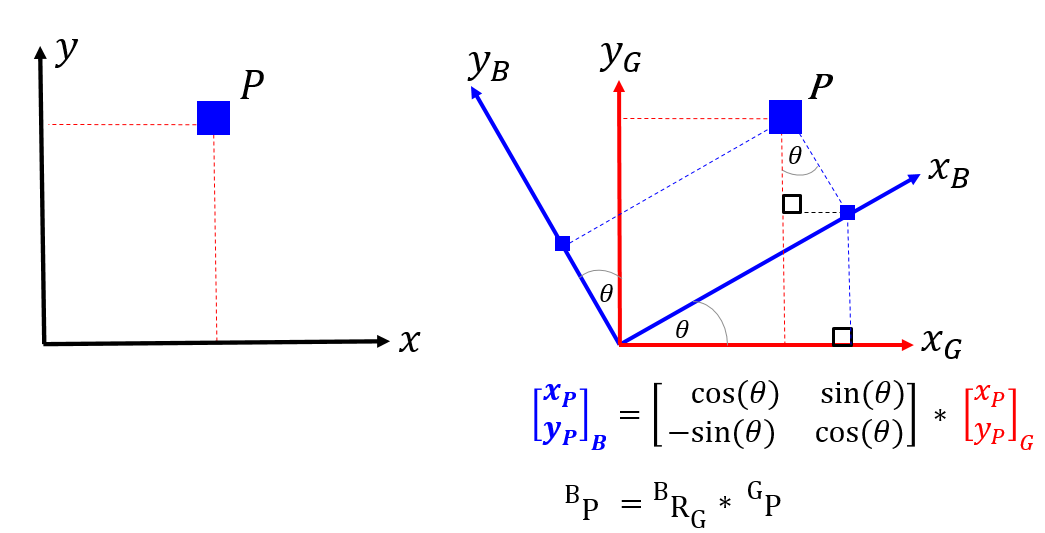 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

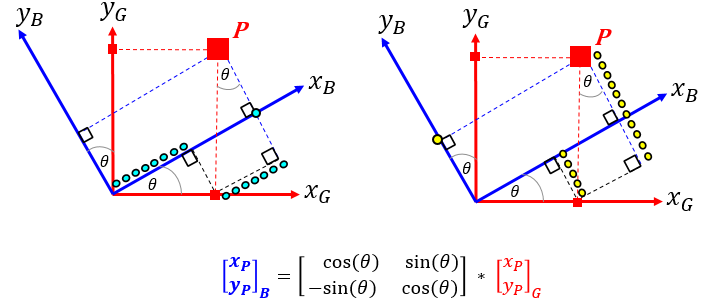

## An example of 3 successive PASSIVE rotations

Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:


$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


So let's get ready to explore:

clear phi          theta          psi   
clear phi_dot      theta_dot      psi_dot
clear phi_ddot  theta_ddot  psi_ddot

syms  phi          theta          psi   
syms  phi_dot      theta_dot      psi_dot
syms  phi_ddot     theta_ddot     psi_ddot

### Create a passive rotation object

OBJ_P = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi], 'SYM')

OBJ_P =   bh_rot_passive_G2B_CLS with properties:

        ang_units: SYM
    num_rotations: 3
          dir_1st: D1Z
          dir_2nd: D2Y
          dir_3rd: D3X
          ang_1st: phi
          ang_2nd: theta
          ang_3rd: psi


### Here are the PASSIVE rotation matrices:

Here's  $\bf  R1Z(\phi_z) $:

R1Z = OBJ_P.get_R1

$$R1Z = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Here's $\bf 
R2Y(\theta_y) $:

R2Y = OBJ_P.get_R2

$$R2Y = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Here's $\bf R3X(\psi_x) $

R3X = OBJ_P.get_R3

$$R3X = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

### Calculate the Direction Cosine Matrix  ${^{B}}R_G $

Recall we earlier said:          $^{B}v  = {^{B}}R_G *  {^{G}}v$

bRg = R3X * R2Y * R1Z

$$bRg = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

### Explore the relationship between BODY rates and EULER rates

As we apply these local frame rotations of ($\phi, \theta, \psi$), we can represent the **angular rates** ($\dot{\phi}, \dot{\theta}, \dot{\matrix{\psi}}$) of the rotating frames into the LOCAL frame co-ordinates. These local frame co-ordinates can then be converted into co-ordinates expressed in the final B frame.  For example, during each of the local axes rotations we can think of there being a START frame and an END frame:

      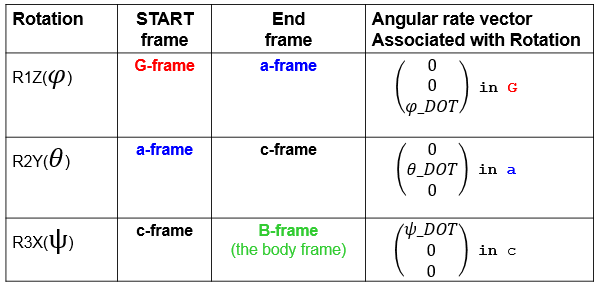

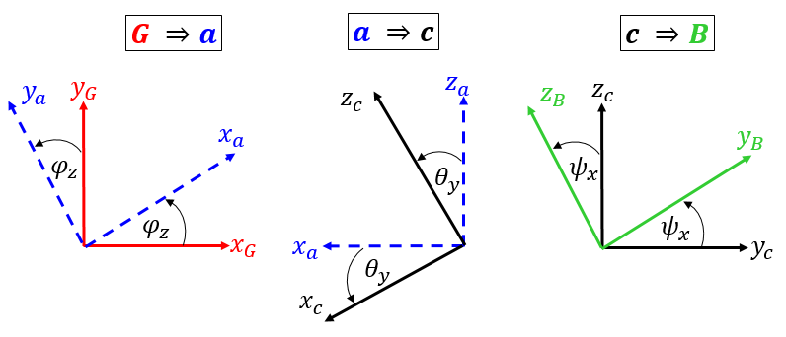

We can express each of the local frame angular velocities into their corresponding components in the final B frame - and we'll use PASSIVE rotation matrices to do this:

aRg = R1Z;
cRa = R2Y;
bRc = R3X;

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\phi}}$ rate:

wb_part_1 = bRc * cRa * aRg * [0;0;phi_dot]   % convert local G into B

$$wb\_part\_1 = \left(\begin{array}{c} -\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\varphi }\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \dot{\varphi }\,\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\theta}}$ rate:

wb_part_2 = bRc * cRa *       [0;theta_dot;0] % convert local a into B

$$wb\_part\_2 = \left(\begin{array}{c} 0\\ \dot{\theta }\,\cos\left(\psi \right)\\ -\dot{\theta }\,\sin\left(\psi \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\psi}}$ rate:

wb_part_3 = bRc *             [psi_dot;0;0]   % convert local c into B

$$wb\_part\_3 = \left(\begin{array}{c} \dot{\psi }\\ 0\\ 0 \end{array}\right)$$

### The total angular velocity expressed in the BODY B frame is therefore

We can now construct the total angular velocity vector expressed in components of the final B frame.

- 
$$_G^{B}\omega_b \equiv \omega_b = f( \dot{ \matrix{\phi}}, \dot{ \matrix{\theta}}, \dot{ \matrix{\psi}}, \phi, \theta, \psi) $$
 

wb = wb_part_1 + wb_part_2 + wb_part_3

$$wb = \left(\begin{array}{c} \dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\,\cos\left(\psi \right)+\dot{\varphi }\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \dot{\varphi }\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\dot{\theta }\,\sin\left(\psi \right) \end{array}\right)$$

### We can write the angular velocity vector $\omega_b$ as a MATRIX equation

Let's say that: $\omega_b ={\left\lbrack \begin{array}{ccc}
\omega_x  & \omega_y  & \omega_z 
\end{array}\right\rbrack }^T \;=\;{\left\lbrack \begin{array}{ccc}
p & q & r
\end{array}\right\rbrack }^T$ , we can write a matrix equation of the form **A.x = b** that describes the relationship between the body rates $\omega_b$ and the Euler rates:

-      
$$A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{p \cr q \cr r}  $$
   

syms p_b q_b r_b

x = [phi_dot, theta_dot, psi_dot].';
    
[A,b] = equationsToMatrix(  wb(1)==p_b, ...
                            wb(2)==q_b, ...
                            wb(3)==r_b, ...
                            x); 

Just to clarify this, let me put each of the 3 elements side by side as  [**A, x, b] ,** where:


$$\matrix{
A & \times & x & = & b \cr
\downarrow & & \downarrow & & \downarrow \cr
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$$


[A, x, b]  

$$ans = \left(\begin{array}{ccccc} -\sin\left(\theta \right) & 0 & 1 & \dot{\varphi } & p_{b}\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) & 0 & \dot{\theta } & q_{b}\\ \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\psi \right) & 0 & \dot{\psi } & r_{b} \end{array}\right)$$

So our Euler rates can be written as:

the_euler_rates = A\b;
the_euler_rates = simplify(the_euler_rates)

$$the\_euler\_rates = \left(\begin{array}{c} \frac{r_{b}\,\cos\left(\psi \right)+q_{b}\,\sin\left(\psi \right)}{\cos\left(\theta \right)}\\ q_{b}\,\cos\left(\psi \right)-r_{b}\,\sin\left(\psi \right)\\ \frac{p_{b}\,\cos\left(\theta \right)+r_{b}\,\cos\left(\psi \right)\,\sin\left(\theta \right)+q_{b}\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} \end{array}\right)$$

## An example of 2 successive PASSIVE rotations

In the Modified Euler analysis of the "Wheel on the pole", we'll allow the body frame to yaw ($\phi$) and pitch ($\theta$) only - the spinning of the wheel will be handled seperately from the angular motion of the "semi" attached body frame.  So our body frame is described by the 2 rotations:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

So what is the angular velocity of teh body frame

aRg       = R1Z;
cRa       = R2Y;

wb_part_1 = R2Y * R1Z * [0;  0;          phi_dot];   % convert local G into B
wb_part_2 = R2Y *       [0;  theta_dot;  0      ];   % convert local a into B

So the body frame angular velocity is:

- 
$$\omega_b$$


wb_for_only_2_rots = wb_part_1  +  wb_part_2

$$wb\_for\_only\_2\_rots = \left(\begin{array}{c} -\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\\ \dot{\varphi }\,\cos\left(\theta \right) \end{array}\right)$$

And the Direction Cosine matrix is:

-   
$$^{B}v  = {^{B}}R_G *  {^{G}}v$$


bRg_for_only_2_rots = R2Y * R1Z

$$bRg\_for\_only\_2\_rots = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ \cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Finally let's explore the $\dot{\omega_b }$ :

syms t my_phi(t)  my_theta(t)

my_phi_dot(t)       = diff(my_phi(t)   , t);
my_theta_dot(t)     = diff(my_theta(t) , t);
my_phi_dot_dot(t)   = diff(my_phi(t)   , t, 2);
my_theta_dot_dot(t) = diff(my_theta(t) , t, 2);

% plain_symbols = [    phi,       theta,       phi_dot,       theta_dot,       phi_ddot,       theta_ddot    ];
% t_symbols     = [ my_phi(t)  my_theta(t), my_phi_dot(t), my_theta_dot(t), my_phi_dot_dot(t), my_theta_dot_dot(t) ];

plain_symbols = [          phi_ddot,            theta_ddot,         phi_dot,         theta_dot,       phi,       theta    ];
t_symbols     = [ my_phi_dot_dot(t),   my_theta_dot_dot(t),   my_phi_dot(t),   my_theta_dot(t),  my_phi(t),  my_theta(t)  ];

my_wb = subs(wb_for_only_2_rots, plain_symbols, t_symbols  );
                             
my_wb_dot = diff(my_wb, t)

$$my\_wb\_dot = \left(\begin{array}{c} -\sin\left({\mathrm{my}}_{\theta }\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{my}}_{\varphi }\left(t\right)-\cos\left({\mathrm{my}}_{\theta }\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{my}}_{\theta }\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{my}}_{\varphi }\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}{\mathrm{my}}_{\theta }\left(t\right)\\ \cos\left({\mathrm{my}}_{\theta }\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{my}}_{\varphi }\left(t\right)-\sin\left({\mathrm{my}}_{\theta }\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{my}}_{\theta }\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{my}}_{\varphi }\left(t\right) \end{array}\right)$$

Subsititute in the original symbols for a nicer display of the results:

-  
$$\dot{\omega_b }$$


my_wb_dot = subs(my_wb_dot,t_symbols , plain_symbols )

$$my\_wb\_dot = \left(\begin{array}{c} -\ddot{\varphi }\,\sin\left(\theta \right)-\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\\ \ddot{\theta }\\ \ddot{\varphi }\,\cos\left(\theta \right)-\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right) \end{array}\right)$$